## Blind Dereverberation Exploiting the Null of Sylvester Matrix with Group Sparse Regularization in the STFT domain

周波数ごとに時間方向のブロックスパースにするやつじゃなくて，時間周波数領域全体でスペクトルの滲みを見て補正できたらいいなのやつ.

not worked

clear

settings

% DGT tool
F = DGTtool("windowLength", 512, "windowShift", 128);

% audio data loading
num_piece = 2;
for i=1:num_piece
    audiofilename = "Goldberg_clav_mono_ds_%d";
    %audiofilename = "9w3r7y_01_%d";
    [temp, fs] =  audioread("input/" + sprintf(audiofilename,i)+".wav");
    ss{i} = temp(:,1);
end
s = [ss{1}; ss{2}];
num_mic = 1;

% ir data loading
[ir, ~] = audioread("BFTLSPACELIBRARY_ChamberAL_11025.wav");
%[ir, fs] = audioread("logic03sWoodenBooth8000.wav");
%[ir{2}, fs(2)] = audioread("../data/BF TL SPACE LIBRARY/Drumbrella/Drumbrella 5'.R.wav");

% ADMM settings
rho = 1.0; % ADMMのペナルティパラメータ (調整用、まずは1.0等から)
alpha = 0.01; % L1正則化の強さ (大きくするほど音漏れがゼロに潰れる)
maxiter = 100;

Malloc

rt = zeros(1,1); % reverb time in sec
obs = cell(1,num_piece); % obs
X = cell(1, num_piece); % STFTs of obs. signal
S = cell(1, num_piece); % STFTs of dry signal
N = zeros(1, num_piece); % length of observation
Lir = zeros(1, 1); % ir length = d + 1
l = zeros(1, num_piece); % length of deconvoluted signal

## resample and shortening

% calculate the reverberation time (RT60)
rt = reverb_time(ir, fs);
ir = ir(1:floor(fs*rt)); ir = ir / norm(ir);
IR = F(ir);
Lir = size(IR, 2);

for j = 1:num_piece
    obs{j} = conv(ss{j}, ir);
    X{j} = F(obs{j});
    N(j) = size(X{j}, 2);
    S{j} = F(ss{j});
end
obsCat = [obs{1}; obs{2}];
D = Lir - 1;
padding = -2;
D = D + padding;
Lir = Lir + padding;

## deconvolution in TF domain

malloc

Fq = size(X{1}, 1);
for i = 1:2, l(i) = N(1, i) - Lir(1) + 1; end
RET1 = zeros(Fq, l(1)); RET2 = zeros(Fq, l(2));
RET1_l21 = zeros(Fq, l(1)); RET2_l21 = zeros(Fq, l(2));
RET_slra = zeros(Fq, sum(l));
% ratio of minimum and the 2nd minimum singular value
singValRatio = zeros(Fq, 1);

% frequency-wise 

時間領域で観測 (x) がクリーン信号 (s) とIR (h) の畳み込みで表されているとする:

$\textrm{Time domain:}~{\bf x} = {\bf s} * {\bf h}$.

それらのDGT (X_f, S_f, H_f) に対して，周波数 f のサブバンドで畳み込みが近似的に成り立っているという立場をとる．


$$\textrm{TF domain}~{\bf X}_f \approx {\bf S}_f * {\bf H}_f
$$


今，独立な二つのクリーン信号 s^1, s^2 があって，同一のIRが畳み込まれたものを観測しているとする:

$\textrm{Time domain} : {\bf x}^{1} = {\bf s}^1 * {\bf h}, {\bf x}^2 = {\bf s}^2* {\bf h}$.

TF領域では，それに対応して


$$\textrm{TF domain} : {\bf X}^{1}_f = {\bf S}^1_f * {\bf H}_f, {\bf X}^2_f = {\bf S}^2_f* {\bf H}_f$$


がある．式をいじって，次を得る:

$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 = {\bf X}^2_f * {\bf S}^1_f,= {\bf S}_f^1*{\bf S}^2_f* {\bf H}_f$.

一つ目の等号の部分から


$$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 - {\bf X}^2_f * {\bf S}^1_f = {\bf 0}$$


これを畳み込み行列を使って表すと，


$$\textrm{TF domain} : \\
{\rm Conv}({\bf X}^{1}_f) {\bf S}_f^2 - {\rm Conv}({\bf X}^2_f) {\bf S}^1_f = {\bf 0}\\ \downarrow\\
\left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]
\left[\begin{array}{c}{ {\bf S}^1_f \\{\bf S}_f^2\end{array}\right]= {\bf 0}
$$


（最後に出てきた式の係数行列はSylvester行列と名前がついている）


$${\rm Sylvester} \overset{\rm def}{=} \left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]$$


Sylvester行列の零空間の基底ベクトルとしてクリーン信号S_f^1, S_f^2 を獲得する．

TF領域での「近似」畳み込みモデルを使っているので，上記のSylvester行列はフルランク行列になってしまっている，

つまり零空間はないのだが，その代わりに最小特異値に対応する右特異ベクトルを使用してクリーン信号の復元を試みる．

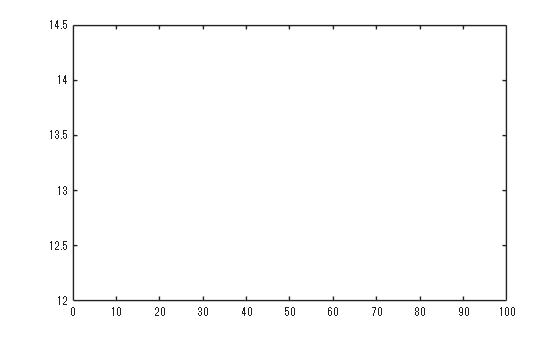

% l21-reg
for f = 1:Fq
    temp = X{1, 1};  X1f = temp(f, :)';
    temp = X{1, 2};  X2f = temp(f, :)';
    [v1, v2] = sylDerevl21(X1f, X2f, l, rho, alpha);
    RET1_l21(f,:) = v1';   RET2_l21(f,:) = v2';
    % RET1W(f,:) = Vf_w(1:l(1))'; RET2W(f,:) = Vf_w(l(1)+1:end)';
end

% para ADMM
T1 = l(1); T2 = l(2);

% 大域的なスペクトログラムの初期化
S1_global = zeros(Fq, T1);    S2_global = zeros(Fq, T2); % init. est.
U1_global = zeros(Fq, T1);    U2_global = zeros(Fq, T2); % init. lagrange

subband_precomputes = cell(Fq, 1);
for f = 1:Fq
    temp = X{1}; X1f = temp(f, :)';
    temp = X{2}; X2f = temp(f, :)';
    Sylvester = [convmtx(X2f, l(1)) convmtx(-X1f, l(2))];
    [~, ~, V] = svd(Sylvester, "econ");
    
    AtA = Sylvester' * Sylvester;
    mu = 10^-6;
    R = chol(AtA + (rho + mu) * eye(size(AtA)));
    
    subband_precomputes{f}.R = R; % 上三角行列を保存
    subband_precomputes{f}.u_init = V(:, end);
    subband_precomputes{f}.XfNorm = norm([X1f; X2f]);
    subband_precomputes{f}.mu = mu;
end

resid_prime = zeros(maxiter, 1);
figure; fig = plot([0,0]); hold on; xlim([0, maxiter])
% ADMMループ開始
for iter = 1:maxiter
    % fprintf('ADMM Iteration %d/%d...\n', iter, maxiter);
    
    % --- 暫定バッファの用意 ---
    V1_math = zeros(Fq, T1);
    V2_math = zeros(Fq, T2);
    
    % =====================================================================
    % 1. 数理ステップ（サブバンドごとに完全並列実行）
    % =====================================================================
    for f = 1:Fq
        % キャッシュから事前計算データを取得
        prep = subband_precomputes{f};
        
        % 大域的なコンセンサス変数と乗数から、この周波数におけるターゲットを構成
        target_v1 = S1_global(f, :)' - U1_global(f, :)';
        target_v2 = S2_global(f, :)' - U2_global(f, :)';
        b  = rho * [target_v1; target_v2] + prep.mu * prep.u_init;
        
        vf = prep.R \ (prep.R' \ b);
        
        % スケールリカバリ
        if norm(vf) >= 1e-12
            vf = vf / norm(vf);
        else
            vf = prep.u_init;
        end
        vf = prep.XfNorm * vf; 
        
        % ピースごとに分割して代入
        V1_math(f, :) = vf(1:l(1))';
        V2_math(f, :) = vf(l(1)+1:end)';
    end
    
    % =====================================================================
    % 2. 正則化ステップ（全帯域を画像として集約し、一括デ・ブラー処理：P&P）
    % =====================================================================
    % 数理ステップの結果に乗数を足し合わせて、DNN（または2Dフィルタ）への入力画像を合成
    V1_for_prox = V1_math + U1_global;
    V2_for_prox = V2_math + U2_global;
    
    % --- 【検証フェーズ】2次元空間での滲み除去プロキシ ---
    % ※ ここでグループスパースの代わりに、縦横両方向の滲みを除去します
    S1_old = S1_global; S2_old = S2_global;
    S1_global = prox_deblur_2d_loc(V1_for_prox);
    S2_global = prox_deblur_2d_loc(V2_for_prox);
    
    % =====================================================================
    % 3. 乗数更新ステップ（大局的な誤差の蓄積）
    % =====================================================================
    U1_old = U1_global; U2_old = U2_global; % 変化量計算用に退避
    U1_global = U1_global + (V1_math - S1_global);
    U2_global = U2_global + (V2_math - S2_global);
    
    % =====================================================================
    % 4. 【追加】ペナルティパラメータ rho の動的調整 (Residual Balancing)
    % =====================================================================
    % 主残差（数理と正則化のズレ）のノルム
    r_norm = norm([(V1_math - S1_global); (V2_math - S2_global)], 'fro');
    
    % 双対残差（正則化変数の前イテレーションからの変化量）のノルム
    s_norm = norm(rho * [(S1_global - S1_old); (S2_global - S2_old)], 'fro'); 
    % ※ループの最初で S1_old = S1_global; して退避させておいてください
    
    % バランス調整（主残差が大きければ rho を大きくして拘束を強める、逆なら緩める）
    if r_norm > 10 * s_norm
        rho = rho * 2;
        % rho が変わったため、precomputes のチョレスキー分解を再計算する必要が出ます。
        % （※ parfor の事前計算を関数化しておき、ここで再呼び出しすると確実です）
    elseif s_norm > 10 * r_norm
        rho = rho / 2;
    end

    resid_prime(iter) = norm([(V1_math - S1_global); (V2_math - S2_global)]);
    if mod(iter, 5) == 1
        fig.XData = iter;
        fig.YData = resid_prime(iter);
        drawnow;
    end
end


% 最終的なクリーン信号の推定スペクトログラム
RET1 = S1_global;
RET2 = S2_global;

### 周波数サブバンドごとに入り込んでるランダムな位相遅延の修復

#### Motivation

畳み込みにおいて，スカラの乗算は畳み込み演算の前後どちらに入れ替えても結合則及び可換則が成立する．


$$\mathbf{x}_f \approx \mathbf{s}_f \ast \hat{\mathbf{h}}_f = (c_f \mathbf{s}_f )\ast (\frac{1}{c_f} \hat{\mathbf{h}}_f)$$


これは、オールパスフィルタがかかっているのとにている。この式からスカラ乗算の不定性を取り除き，真のモデル $\mathbf{x}_f \approx \mathbf{s}_f \ast \mathbf{h}_f$ と一致させるためには，サブバンドIRベクトル $\hat{\mathbf{h}}_f$ に対応する時間領域のRIRに制約（直接音は周波数に関係せず全てのサブバンドで同じ時刻に到達するなどの，現実的に満たすべきものなどが挙げられる）をかけ，制約を満たす位相回転 $c_f$を求める必要がある．位相回転は、時間領域の逆畳み込みでIRを推定し、その位相から計算する。

retl21{1} = F.pinv(RET1_l21);   retl21{2} = F.pinv(RET2_l21);

index computed (OLA)



% ⑦ 最終的な残響除去音声の出力
ret{1} = F.pinv(RET1);
ret{2} = F.pinv(RET2);

Display


for i=1:2
    len_ss = length(ss{i});
    len_ret = length(ret{i});
    if len_ss > len_ret
        ss{i} = ss{i}(1:len_ret);
        len_ss = len_ret;
    end
    [SDR,SIR,SAR,perm] = bss_eval_sources(obs{i}(1:len_ss)', ss{i}');
    fprintf("obs: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(retl21{i}(1:len_ss)', ss{i}');
    fprintf("ret(mid): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret{i}(1:len_ss)', ss{i}');
    fprintf("ret: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    audiowrite("output/" + sprintf(audiofilename +"_wet.wav", i), obs{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_l21_phased_pad=%d.wav", i, padding), ret{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_l21_pad=%d.wav", i, padding), retl21{i}, fs)
end

obs: SDR -2.082, SIR Inf, SAR -2.082


ret(mid): SDR 7.167, SIR Inf, SAR 7.167


ret: SDR -0.732, SIR Inf, SAR -0.732


obs: SDR -0.594, SIR Inf, SAR -0.594


ret(mid): SDR 6.784, SIR Inf, SAR 6.784


ret: SDR -1.880, SIR Inf, SAR -1.880


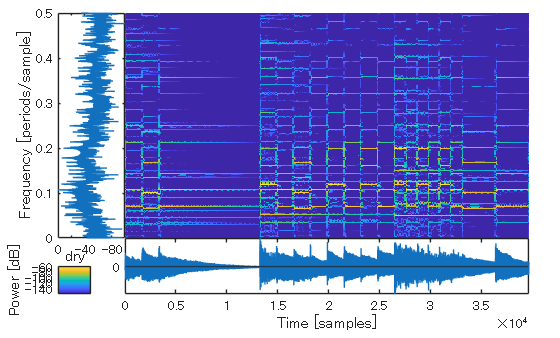


F.plotReassign(ss{1});title("dry"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_dry.png")

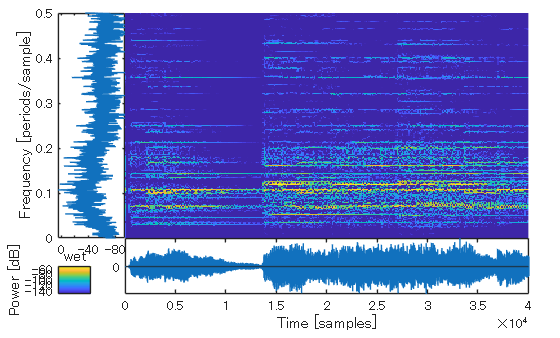

F.plotReassign(obs{1}(1:length(ret{1}))); title("wet"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_wet.png")

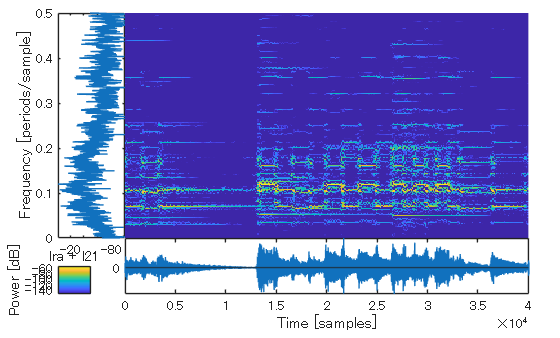

F.plotReassign(retl21{1}); title("lra + l21");
saveas(gcf, "result/" + sprintf(audiofilename + "_ret_pad=%d.png",1, padding) )

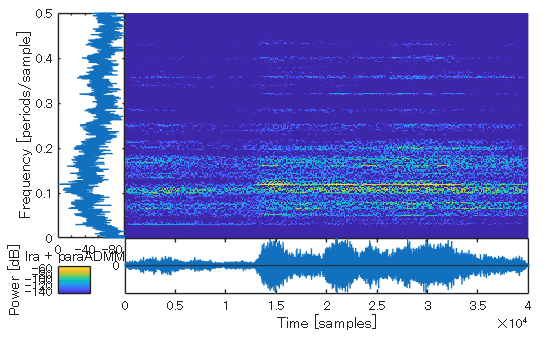

F.plotReassign(ret{1}); title("lra + paraADMM");
saveas(gcf, "result/" + sprintf(audiofilename + "_ret_phased_pad=%d.png",1, padding) )

- どの結果も時間のマイナス方向に信号が漏れ出ているのがきになる．

function S_out = prox_deblur_2d_loc(V_complex)
    % V_complex: [Fq x T] の複素スペクトログラム
    
    V_mag = abs(V_complex);
    V_phase = exp(1j * angle(V_complex));
    
    % 1. 2次元フィルタで縦横の滲みを叩く
    % --- 2次元画像処理による暫定シャープ化（DNN接続前の検証用） ---
    % 縦（周波数）方向と横（時間）方向の滲み（ブラー）を抑え、エッジを引き締める
    % ここではMATLAB標準の2次元メディアンフィルタと、コントラスト強調の組み合わせ例
    % ※ 実際の設定（Fq, T）に合わせて近傍サイズ [縦, 横] を調整してください
    V_mag_sharp = medfilt2(V_mag, [3, 5]); 
    
    % 2. 【超重要】エネルギーの再スケーリング（スケール崩壊の防止）
    % フィルタをかける前の全エネルギーと、かけた後の全エネルギーの比を計算
    scale_factor = norm(V_mag, 'fro') / (norm(V_mag_sharp, 'fro') + eps);
    
    % フィルタ後の画像に掛け直して、エネルギーを完全に保存させる
    V_mag_sharp = V_mag_sharp * scale_factor;

    % お好みで、時間方向の残響テイルをカットするための非線形収縮なども有効です
    % V_mag_sharp = max(V_mag_sharp - threshold, 0); 
    
    % --- 【後ほどDNNへ差し替える箇所】 ---
    % もし2D-U-Netモデル（net_sharpener）をロードしている場合は、以下のように差し替えます
    % V_log = log10(V_mag + 1e-5);
    % V_input = reshape(single(V_log), [size(V_log,1), size(V_log,2), 1, 1]);
    % S_log_predicted = gather(predict(net_sharpener, gpuArray(V_input)));
    % S_mag_sharp = 10.^(S_log_predicted) - 1e-5;
    % V_mag_sharp = max(S_mag_sharp, 0);
    
    % 複素スペクトログラムの再構成
    S_out = V_mag_sharp .* V_phase;
end

グループスパース制約を廃止し、時間周波数（2次元）領域でのデ・ブラー処理（DNN）を統合するための「全帯域協調型並列Plug-and-Play ADMM（Global Consensus P&P-ADMM）」の数理的定式化を行います。

本定式化の最大のポイントは、「各サブバンドの物理方程式（CR法）」と「全帯域を束ねた2次元複素スペクトログラムの一貫性（DNN）」を、共通の補助変数（コンセンサス変数）を介して結びつける点にあります。

1. 目的関数の定式化

全周波数ビン数（サブバンド数）を $F$、時間フレーム数を $T$ とします。

周波数ビン $f \in \{1, \dots, F\}$ における、提案法のクリーン信号ベクトルを $\mathbf{s}_f \in \mathbb{C}^T$ とします。

ここで、全サブバンドを縦に積み上げた全帯域複素スペクトログラム行列を $\mathbf{S} = [\mathbf{s}_1, \mathbf{s}_2, \dots, \mathbf{s}_F]^T \in \mathbb{C}^{F \times T}$ と定義します。

グループスパースに代わり、この2次元複素行列 $\mathbf{S}$ 全体に対して、時間・周波数両方向の滲みを除去する正則化項（DNNの暗黙的な事前分布） $g(\mathbf{S})$ を課します。全体の最適化問題は以下のように定式化されます。

$$\min_{\mathbf{s}_1, \dots, \mathbf{s}_F, \mathbf{S}} \sum_{f=1}^{F} f_f(\mathbf{s}_f) + g(\mathbf{S}) \quad \text{subject to} \quad \mathbf{s}_f = [\mathbf{S}]_f \quad (\forall f)$$

* $f_f(\mathbf{s}_f)$ : 周波数 $f$ におけるCross-Relation法のデータ誤差項（物理制約）。単チャネル観測から構成したSylvester行列の零空間条件などに相当します（例：$\frac{1}{2}\|\mathbf{A}_f \mathbf{s}_f\|^2$）。

* $g(\mathbf{S})$ : 2次元スペクトログラムの構造的正則化項（デ・ブラー）。

* $[\mathbf{S}]_f$ : 2次元行列 $\mathbf{S}$ から、周波数 $f$ の行ベクトル（時間波形）を抽出する操作。

2. 拡張ラグランジュ関数の構成

各サブバンドの独立な変数 $\mathbf{s}_f$ と、大域的な一貫性を保つための変数 $\mathbf{S}$ を一致させる（コンセンサスをとる）ため、ラグランジュ乗数ベクトル $\mathbf{u}_f \in \mathbb{C}^T$ とペナルティパラメータ $\rho > 0$ を導入し、拡張ラグランジュ関数 $\mathcal{L}_\rho$ を構成します。

$$\mathcal{L}_\rho(\{\mathbf{s}_f\}, \mathbf{S}, \{\mathbf{u}_f\}) = \sum_{f=1}^{F} \left( f_f(\mathbf{s}_f) + \frac{\rho}{2} \left\| \mathbf{s}_f - [\mathbf{S}]_f + \mathbf{u}_f \right\|_2^2 \right) + g(\mathbf{S}) - \sum_{f=1}^{F} \frac{\rho}{2}\|\mathbf{u}_f\|_2^2$$

(※扱いやすさのため、乗数項はスケーリング型表現（Scaled-form）で記述しています。)

3. ADMMによる反復更新式の導出（並列アルゴリズム）

この拡張ラグランジュ関数を、$\mathbf{s}_f \rightarrow \mathbf{S} \rightarrow \mathbf{u}_f$ の順で交互に最小化します。これにより、アルゴリズムは「サブバンドごとの完全並列処理」と「全帯域の一括集約（DNN）」の綺麗なペアに分解されます。

反復回数を $k$ とすると、更新式は以下の3ステップになります。

ステップ 1: サブバンド並列の数理更新 ($\mathbf{s}_f$ の更新)

各周波数ビン $f$ において、独立に以下の二次形式の最小化問題を解きます。

$$\mathbf{s}_f^{(k+1)} = \arg\min_{\mathbf{s}_f} \left( f_f(\mathbf{s}_f) + \frac{\rho}{2} \left\| \mathbf{s}_f - [\mathbf{S}^{(k)}]_f + \mathbf{u}_f^{(k)} \right\|_2^2 \right)$$

* 物理的意味: 前のイテレーションでDNNが綺麗にしたスペクトログラムの形状（$[\mathbf{S}^{(k)}]_f - \mathbf{u}_f^{(k)}$）から大きく離れないように拘束しつつ、自分の周波数のCross-Relation方程式を最も満たすように時間波形 $\mathbf{s}_f$ をフィッティングします。

* $f_f$ が最小二乗形式（$\frac{1}{2}\|\mathbf{A}_f \mathbf{s}_f\|^2$）であれば、このステップは単なる線形連立方程式の解（行列の逆変換、または擬似逆行列の乗算）になり、各サブバンドで完全に並列に一瞬で計算できます。

ステップ 2: 全帯域一括のP&Pデ・ブラー更新 ($\mathbf{S}$ の更新)

すべての $\mathbf{s}_f^{(k+1)}$ の更新が終わったら、これらを一度縦に積み上げて、暫定の複素スペクトログラム行列 $\mathbf{V}^{(k+1)} \in \mathbb{C}^{F \times T}$ を合成します。

$$\mathbf{V}^{(k+1)} = \begin{bmatrix} (\mathbf{s}_1^{(k+1)} + \mathbf{u}_1^{(k)})^T \\ (\mathbf{s}_2^{(k+1)} + \mathbf{u}_2^{(k)})^T \\ \vdots \\ (\mathbf{s}_F^{(k+1)} + \mathbf{u}_F^{(k)})^T \end{bmatrix}$$

この $\mathbf{V}^{(k+1)}$ に対し、大域的な正則化 $g(\mathbf{S})$ を適用します。これが近接演算子（Proximal Operator）の定義そのものになります。

$$\mathbf{S}^{(k+1)} = \text{prox}_{g/\rho} (\mathbf{V}^{(k+1)}) = \arg\min_{\mathbf{S}} \left( g(\mathbf{S}) + \frac{\rho}{2} \|\mathbf{S} - \mathbf{V}^{(k+1)}\|_F^2 \right)$$

* P&P（深層学習）への置き換え: 数理最適化の理論（Plug-and-Play）に基づき、この近接演算子 $\text{prox}_{g/\rho}(\cdot)$ の計算を、学習済みの2次元デ・ブラーDNN（2D-U-Net）による順方向の推論処理（predict）に丸ごと置き換えます。 $$\mathbf{S}^{(k+1)} = \text{DNN}_{\text{deblur}} \left( \mathbf{V}^{(k+1)} \right)$$  DNNが、縦（周波数リーク）と横（残響テイル）の滲みを画像処理の文脈で一括して引き締め、クリーンな複素スペクトログラム $\mathbf{S}^{(k+1)}$ を出力します。

ステップ 3: ラグランジュ乗数の更新 ($\mathbf{u}_f$ の更新)

最後に、数理の予測値とDNNの予測値の「ズレ（誤差）」を蓄積し、次回の拘束力を調整するために、各サブバンドで独立に乗数を更新します。

$$\mathbf{u}_f^{(k+1)} = \mathbf{u}_f^{(k)} + \left( \mathbf{s}_f^{(k+1)} - [\mathbf{S}^{(k+1)}]_f \right)$$

4. この定式化によるメリット

1. 数理的な厳密性の担保: 「周波数ごとに独立にCR法を解く」という吉野さんのプログラムのコアが、ステップ1（並列数理更新）としてそのまま無傷で残ります。数学的に美しい並列計算（Parallel/Consensus ADMM）の枠組みに乗っているため、論文の数理セクションの格調が跳ね上がります。

2. グループスパースの完全な上位互換: 従来のグループスパースは、ステップ2の $\text{prox}$ 演算として「時間方向のソフトしきい値処理」を周波数ごとに独立に適用していただけでした。それを「全帯域を束ねた2次元DNN」に変えるだけなので、アルゴリズムのトポロジー（構造）を変更することなく、制約の次元だけを1次元から2次元（縦横の滲み除去）へとエレガントに拡張できます。

まずはこの更新数理（ステップ1〜3のループ）をプログラム上に構築し、ステップ2の $\text{prox}$ の部分に（DNNを入れる前のテストとして）MATLABの2次元画像処理フィルタなどを挟んで挙動を確認する、という吉野さんの提案された手順へ進む準備が整いました。